# Compares the three numerical differentiation methods.

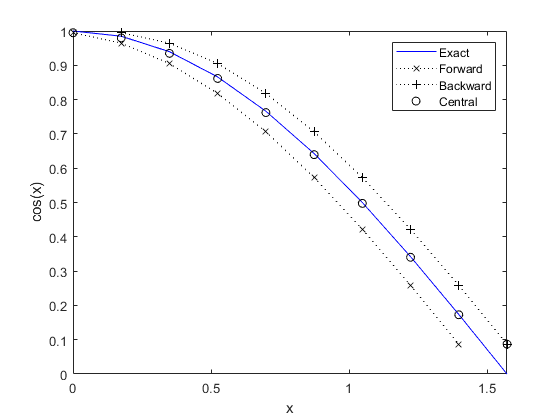

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
n = 10;
x = linspace(0, pi/2, n);
y = sin(x);
y1 = cos(x);
plot(x, y1, 'b-'), hold on
axis([0, pi/2, 0, 1])
y1 = diff(y)./diff(x);
plot(x(1:n-1), y1, 'kx:')
plot(x(2:n), y1, 'k+:')
y1 = gradient(y, x);
plot(x, y1, 'ko')
xlabel('x')
ylabel('cos(x)')
legend('Exact', 'Forward', 'Backward', 'Central')

# Demonstrates numerical integration with the function trapz, which uses a trapezoidal rule.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
n = 11;
x = linspace(0,10,n);
y = 20 + x.^2;
plot(x, y, 'k'), hold on
plot([x;x], [zeros(1,n);y], 'k')
axis([0, 10, 0, 120])
xlabel('x')
ylabel('y = 20+x^2')
A = trapz(x, y)
text(1, 40, ['Area = ', num2str(A)])

# Calculates the length of a curve.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
n = 500;
t = linspace(0,3*pi,n);
x = sin(2*t);
y = cos(t);
z = t;
plot3(x, y, z)
axis vis3d, box on, grid on
xlabel('x'), ylabel('y'), zlabel('z')
f = sqrt(gradient(x,t).^2+gradient(y,t).^2+gradient(z,t).^2);
L = trapz(t, f)

# Generates a convergence curve for the length calculation

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
k = 0;
for n = 100:100:2000;
    t = linspace(0,3*pi,n);
    x = sin(2*t);
    y = cos(t);
    z = t;
    f = sqrt(gradient(x,t).^2+gradient(y,t).^2+gradient(z,t).^2);
    k = k+1;
    L(k) = trapz(t, f);
end
plot([100:100:2000], L, 'o-'), hold on
plot([0, 2000], [L(k), L(k)])
text(1200,L(k)+0.003, ['Length = ', num2str(L(k))])
xlabel('Number of Segments')
ylabel('Calculated Length')

# Calculates the length of the curve using the function integral.

L = integral(@fun, 0, 3*pi)

L = 17.2218

# Calculates the area and centroid bounded by two curves

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
syms x y
fx = x+2;
gx = x^2;
fplot(fx), hold on, fplot(gx)
axis([-3,3,0,6])
legend('y = x+2', 'y = x^2', 'Location', 'southeast')
title('Two Curves')
eq1 = (y == fx);
eq2 = (y == gx);
sol = solve(eq1, eq2);
x1 = double(sol.x(1))
x2 = double(sol.x(2))
y1 = double(sol.y(1))
y2 = double(sol.y(2))
funA = @(x) abs((x+2)-(x.^2));
A = integral(funA,x1,x2)
funXc = @(x) x.*abs((x+2)-(x.^2));
funYc = @(x) abs((x+2).^2-(x.^4));
xc = integral(funXc,-1,2)/A
yc = integral(funYc,-1,2)/(2*A)

# Double Integral: Volume Under Stadium Dome

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
x = -100:2:100;
y = -60:2:60;
[X, Y] = meshgrid(x, y);
Z = (17200 - X.^2 - 2*Y.^2)/200;
surf(X,Y,Z), axis vis3d equal
A = trapz(x, Z, 2);
V = trapz(y, A)
fun2 = @(s,t) (17200 - s.^2 - 2*t.^2)/200;
V = integral2(fun2, -100, 100, -60, 60)

# Placing Weight on Spring - Scale Calculates x(t).

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
Example11_06()

# Solves an initial value problem.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
Example11_08()

# Solves an initial value problem.

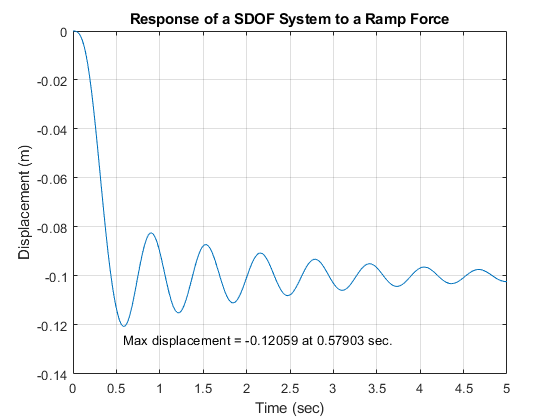

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
Example11_09()

# Solves a boundary value problem.

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
Example11_10()

# Solves a initial boundary value problem

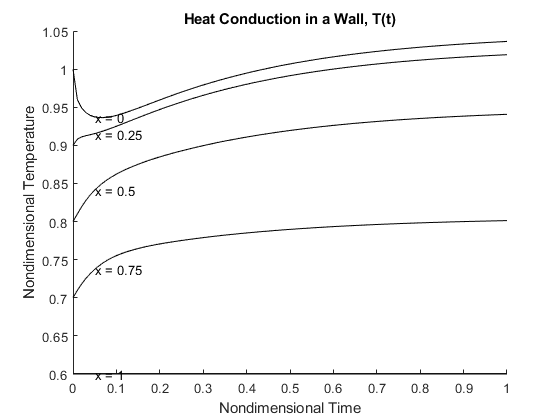

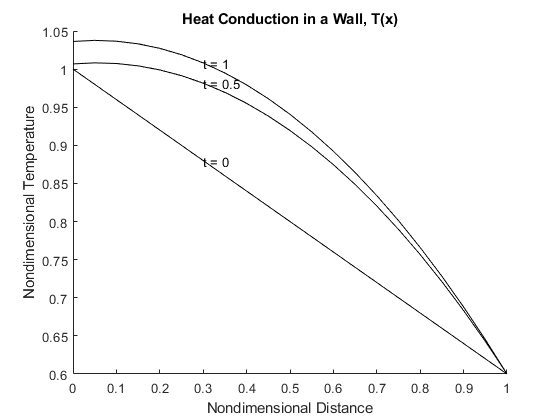

clc % 清除command window
clear all % 清除WorkSpace變數
close all %  關閉所有視窗
Example11_11()

function dL = fun(t)
x = sin(2*t);
y = cos(t);
z = t;
dL = sqrt(gradient(x,t).^2+gradient(y,t).^2+gradient(z,t).^2);
end
function Example11_11
    A = 0.4; B = 0.05; T1 = 0.6;
    x = linspace(0, 1, 21);
    t = linspace(0, 1, 101);
    T = pdepe(0, @pdefun, @icfun, @bcfun, x, t);
    hold on
    for k = [1,6,11,16,21]
        plot(t,T(:,k),'k-')
        text(0.05,T(6,k), ['x = ', num2str(x(k))])
    end
    xlabel('Nondimensional Time')
    ylabel('Nondimensional Temperature')
    title('Heat Conduction in a Wall, T(t)')

    figure, hold on
    for k = [1, 51, 101]
        plot(x,T(k,:),'k-')
        text(0.3,T(k,7), ['t = ', num2str(t(k))])
    end
    xlabel('Nondimensional Distance')
    ylabel('Nondimensional Temperature')
    title('Heat Conduction in a Wall, T(x)')

        function [c, f, s] = pdefun(x,t,T,Tprime)
            c = 1;
            f = Tprime;
            s = 1;
        end

        function Tinit = icfun(x)
            Tinit = 1-A*x;
        end

        function [pa,qa,pb,qb] = bcfun(a,Ta,b,Tb,t)
            pa = -B*Ta;
            qa = 1;
            pb = Tb-T1;
            qb = 0;
        end
end
function Example11_10
w = -0.1; h = 0.1; L = 8; E = 2.1e11; q = 500;
I = w*h^3/12;
solinit = bvpinit(linspace(0,L,1000), [1, 1, 1, 1]);
sol = bvp4c(@odefun, @bcfun, solinit);
x = sol.x; y = sol.y(1,:);
plot(x, y*1000)
xlabel('x (m)'), ylabel('y (mm)')
title('Deflection of Uniformly Loaded and Simply Supported Beam')
[M, I] = min(y);
text(x(I), M*1000, ['Maximum deflection = ', num2str(-M*1000)])

    function yprime = odefun(x, y)
        yprime = zeros(4,1);
        yprime(1) = y(2);
        yprime(2) = y(3);
        yprime(3) = y(4);
        yprime(4) = q/(E*I);
    end

    function residual = bcfun(y0, yL)
        residual = zeros(4,1);
        residual(1) = y0(1);
        residual(2) = y0(3);
        residual(3) = yL(1);
        residual(4) = yL(3);
    end
end
function Example11_09
m = 1; c = 1; k = 100; W = -10; T0 = 0.5;
[time, sol] = ode45(@fun, [0,5], [0,0]);
plot(time,sol(:,1)), grid on
xlabel('Time (sec)'), ylabel('Displacement (m)')
title('Response of a SDOF System to a Ramp Force')
[M, I] = min(sol(:,1));
text(time(I), M-0.005, ['Max displacement = ', ...
    num2str(M), ' at ', num2str(time(I)), ' sec.'])

    function ydot = fun(t, y)
        force = W*t/T0*(t<T0)+W*(t>=T0);
        ydot(1) = y(2);
        ydot(2) = (1/m)*(force - c*y(2) - k*y(1));
        ydot = ydot';
    end
end
function Example11_08
m = 1; c = 1; k = 100; delta = 0.2;
[time, sol] = ode45(@fun, [0,2], [delta, 0]);
plot(time, sol(:,1));
xlabel('Time (sec)')
ylabel('Displacement (m)')
yyaxis right
plot(time, sol(:,2));
ylabel('Velocity (m/s)')
title('Free Vibration of a SDOF Damped System')
grid on

    function ydot = fun(t, y)
        ydot(1) = y(2);
        ydot(2) = (-k*y(1)-c*y(2))/m;
        ydot = ydot';
    end
end
function Example11_06
    m = 1; c = 1; k = 100; W = -10; T0 = 0.5;
    omega = sqrt(k/m); cc = 2*m*omega; zeta = c/cc; t0 = omega*T0;
    n = 200; t = linspace(0, 50, n);
    for i = 1:n
        x(i) = (W/k)*(h(t(i))*(t(i)>0)-h(t(i)-t0)*(t(i)>t0));
    end
    plot(t/omega, x), grid on
    xlabel('Time (sec)'), ylabel('Displacement (m)')
    title('Respnse of a SDOF System to a Ramp Force')
    [M,I] = min(x);
    text(t(I)/omega, M-0.005, ['Max displacement = ', ...
        num2str(M), ' at ', num2str(t(I)/omega), ' sec.'])

    function out = h(t)
        out = (1/(t0*sqrt(1-zeta^2)))*integral(@fun, 0, t);

        function out = fun(tau)
            out = tau.*exp(-zeta*(t-tau)).*sin((t-tau)*sqrt(1-zeta^2));
        end
    end
end